**Image Scanning using Webcam**

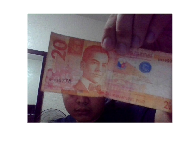

% Connect to selected webcam
cam = webcam("Integrated Camera",...
	"Resolution","640x480");

% Acquire webcam image
money = snapshot(cam);

% Show acquired image
imshow(money);


% Clear existing webcam connection
clear cam
imshow(money)

**Converting the scanned image to HSV for processing**

hsvimg=rgb2hsv(money);
hue=hsvimg(:,:,1);
saturation=hsvimg(:,:,2);
value=hsvimg(:,:,3);

**Text to Speech Function **

%{
NET.addAssembly('System.Speech');
speaker=System.Speech.Synthesis.SpeechSynthesizer;
speaker.Rate=0.1;
Speak(speaker,'You have scanned an image using your device')
%}

**For loop used in scanning every pixel from the image**

bluepixel = 0;
yellowpixel = 0;
greenpixel = 0;
purplepixel = 0;
redpixel = 0;
orangepixel = 0;

for i=1:480
    for j=1:640
        hueThreshMin1k = 0.469;
        hueThreshMax1k = 0.597;
        satThreshMin1k = 0.164;
        satThreshMax1k = 1.00;
        valThreshMin1k = 0.292;
        valThreshMax1k = 0.969;

        hueThreshMin2h = 0.261;
        hueThreshMax2h = 0.382;
        satThreshMin2h = 0.113;
        satThreshMax2h = 0.667;
        valThreshMin2h = 0.290;
        valThreshMax2h = 0.941;

        hueThreshMin5h = 0.129;
        hueThreshMax5h = 0.203;
        satThreshMin5h = 0.060;
        satThreshMax5h = 1.00;
        valThreshMin5h = 0.247;
        valThreshMax5h = 1;

        hueThreshMin1h = 0.750;
        hueThreshMax1h = 0.853;
        satThreshMin1h = 0.105;
        satThreshMax1h = 0.531;
        valThreshMin1h = 0.246;
        valThreshMax1h = 0.887;

        hueThreshMin50 = 0.922;
        hueThreshMax50 = 0.998;
        satThreshMin50 = 0.169;
        satThreshMax50 = 0.821;
        valThreshMin50 = 0.559;
        valThreshMax50 = 0.969;

        hueThreshMin20 = 0.060;
        hueThreshMax20 = 0.119;
        satThreshMin20 = 0.133;
        satThreshMax20 = 0.692;
        valThreshMin20 = 0.533;
        valThreshMax20 = 0.985;

        if ((hue(i,j)>=hueThreshMin1k)&(hue(i,j)<=hueThreshMax1k))
            hcount1k = 1;
        else
            hcount1k = 0;
        end
        if ((saturation(i,j)>=satThreshMin1k)&(saturation(i,j)<=satThreshMax1k))
            scount1k = 1;
        else
            scount1k = 0;
        end
        if ((value(i,j)>=valThreshMin1k)&(value(i,j)<=valThreshMax1k))
            vcount1k = 1;
        else
            vcount1k = 0;
        end
        if ((hcount1k == 1) & (scount1k == 1) & (vcount1k==1))
            bluepixel = bluepixel + 1;
        end

        if ((hue(i,j)>=hueThreshMin2h)&(hue(i,j)<=hueThreshMax2h))
            hcount2h = 1;
        else
            hcount2h = 0;
        end
        if ((saturation(i,j)>=satThreshMin2h)&(saturation(i,j)<=satThreshMax2h))
            scount2h = 1;
        else
            scount2h = 0;
        end
        if ((value(i,j)>=valThreshMin2h)&(value(i,j)<=valThreshMax2h))
            vcount2h = 1;
        else
            vcount2h = 0;
        end
        if ((hcount2h == 1) & (scount2h == 1) & (vcount2h==1))
            greenpixel = greenpixel + 1;
        end
        
        if ((hue(i,j)>=hueThreshMin5h)&(hue(i,j)<=hueThreshMax5h))
            hcount5h = 1;
        else
            hcount5h = 0;
        end
        if ((saturation(i,j)>=satThreshMin5h)&(saturation(i,j)<=satThreshMax5h))
            scount5h = 1;
        else
            scount5h = 0;
        end
        if ((value(i,j)>=valThreshMin5h)&(value(i,j)<=valThreshMax5h))
            vcount5h = 1;
        else
            vcount5h = 0;
        end
        if ((hcount5h == 1) & (scount5h == 1) & (vcount5h==1))
            yellowpixel = yellowpixel + 1;
        end

        if ((hue(i,j)>=hueThreshMin1h)&(hue(i,j)<=hueThreshMax1h))
            hcount1h = 1;
        else
            hcount1h = 0;
        end
        if ((saturation(i,j)>=satThreshMin1h)&(saturation(i,j)<=satThreshMax1h))
            scount1h = 1;
        else
            scount1h = 0;
        end
        if ((value(i,j)>=valThreshMin1h)&(value(i,j)<=valThreshMax1h))
            vcount1h = 1;
        else
            vcount1h = 0;
        end
        if ((hcount1h == 1) & (scount1h == 1) & (vcount1h==1))
            purplepixel = purplepixel + 1;
        end

        if ((hue(i,j)>=hueThreshMin50)&(hue(i,j)<=hueThreshMax50))
            hcount50 = 1;
        else
            hcount50 = 0;
        end
        if ((saturation(i,j)>=satThreshMin50)&(saturation(i,j)<=satThreshMax50))
            scount50 = 1;
        else
            scount50 = 0;
        end
        if ((value(i,j)>=valThreshMin50)&(value(i,j)<=valThreshMax50))
            vcount50 = 1;
        else
            vcount50 = 0;
        end
        if ((hcount50 == 1) & (scount50 == 1) & (vcount50 == 1))
            redpixel = redpixel + 1;
        end

        if ((hue(i,j)>=hueThreshMin20)&(hue(i,j)<=hueThreshMax20))
            hcount20 = 1;
        else
            hcount20 = 0;
        end
        if ((saturation(i,j)>=satThreshMin20)&(saturation(i,j)<=satThreshMax20))
            scount20 = 1;
        else
            scount20 = 0;
        end
        if ((value(i,j)>=valThreshMin20)&(value(i,j)<=valThreshMax20))
            vcount20 = 1;
        else
            vcount20 = 0;
        end
        if ((hcount20 == 1) & (scount20 == 1) & (vcount20 == 1))
            orangepixel = orangepixel + 1;
        end
        j=j+1;
    end
    i=i+1;
end

if ((bluepixel>greenpixel) & (bluepixel>yellowpixel) & (bluepixel>purplepixel) & (bluepixel>orangepixel) & (bluepixel>redpixel))
    disp('blue');
    %Speak(speaker,'The image you have scanned is one thousand philippine pesos')
end
if ((greenpixel>bluepixel) & (greenpixel>yellowpixel) & (greenpixel>purplepixel) & (greenpixel>orangepixel) & (greenpixel>redpixel))
    disp('green')
    %Speak(speaker,'The image you have scanned is two hundred philippine pesos')
end
if ((yellowpixel>greenpixel) & (yellowpixel>bluepixel) & (yellowpixel>purplepixel) & (yellowpixel>orangepixel) & (yellowpixel>redpixel))
    disp('yellow')
    %Speak(speaker,'The image you have scanned is five hundred philippine pesos')
end
if ((purplepixel>greenpixel) & (purplepixel>bluepixel) & (purplepixel>yellowpixel) & (purplepixel>orangepixel) & (purplepixel>redpixel)) 
    disp('purple')
    %Speak(speaker,'The image you have scanned is one hundred philippine pesos')
end
if ((redpixel>greenpixel) & (redpixel>bluepixel) & (redpixel>purplepixel) & (redpixel>orangepixel) & (redpixel>yellowpixel))
    disp('red')
    %Speak(speaker,'The image you have scanned is fifty philippine pesos')
end
if ((orangepixel>greenpixel) & (orangepixel>bluepixel) & (orangepixel>purplepixel) & (orangepixel>yellowpixel) & (orangepixel>redpixel))
    disp('orange')
    %Speak(speaker,'The image you have scanned is twenty philippine pesos')
end

orange
